# Exercise 1: Plot Histogram of RGB Image Intensities

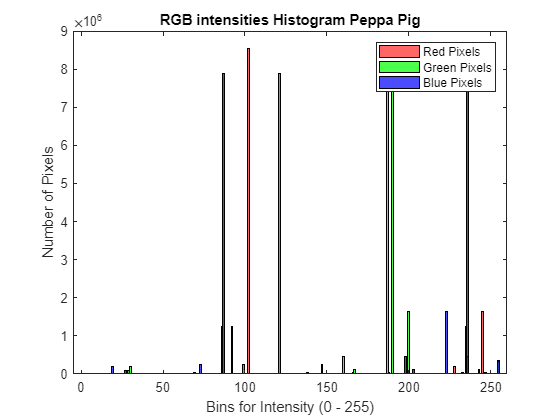

plotHIR =   Histogram with properties:

             Data: [3777×5612 uint8]
           Values: [2 7 12 37 79 199 458 970 2091 83287 1782 840 469 234 115 62 45 26 30 21 29 33 30 28 37 27 28 34 23 28 41 36 52 61 106 148 277 528 838 751 2257 1123 554 399 279 169 124 128 92 68 103 77 74 79 61 69 76 85 60 84 68 66 74 83 73 95 70 … ]
          NumBins: 236
         BinEdges: [19.5000 20.5000 21.5000 22.5000 23.5000 24.5000 25.5000 26.5000 27.5000 28.5000 29.5000 30.5000 31.5000 32.5000 33.5000 34.5000 35.5000 36.5000 37.5000 38.5000 39.5000 40.5000 41.5000 42.5000 43.5000 44.5000 45.5000 46.5000 … ]
         BinWidth: 1
        BinLimits: [19.5000 255.5000]
    Normalization: 'count'
        FaceColor: [1 0 0]
        EdgeColor: [0 0 0]

  Show 

x = "peppa.jpg";
plotHIR = plotHistogramInRGB(x)

function [hist_red, hist_blue, hist_green] = plotHistogramInRGB(x)
imgIn = imread(x);
r = imgIn(:,:,1);
g = imgIn(:,:,2);
b = imgIn(:,:,3);
hist_red = histogram(r,'BinMethod', 'integers', 'FaceColor','r');
hold on;
hist_green = histogram(g,'BinMethod', 'integers', 'FaceColor','g',FaceAlpha=0.7);
hist_blue = histogram(b,'BinMethod', 'integers', 'FaceColor','b',FaceAlpha=0.7);
xlabel("Bins for Intensity (0 - 255)")
ylabel("Number of Pixels")
title("RGB intensities Histogram Peppa Pig")
xlim([-5 260])
legend('Red Pixels', 'Green Pixels', 'Blue Pixels')
end